# **问题6：进行过哪些维修**

**假设上下行比例相同，只考虑单独使用情况，故而可知踩踏概率分布。**

clear;clc;
% 设置随机种子
rng(42);
load F.mat;
load P.mat;
% 参数设置
L1 = 1.5; % 单位：m
L2 = 0.40; % 单位：m
m = 120; % 网格大小
n = 32; % 网格大小
T_original = 120;% 120月（距今多久）
delta_L = L1/m;
delta_S = delta_L*delta_L;
Q_avg=500:500:10000; % 单位时间内平均人流量
simu_index=10; % 使用哪个Q_avg进行模拟

T_repair = 20;% 实际修缮的时间节点（距今多久）
a_factor = 1.1 ;% 新旧材料的磨损系数的比值,a_factor>1,则新材料更不耐磨

为了简化分析，我们假设对翻新区域只进行了一次翻新

**问题可以重新叙述为确定【翻新的区域】和【翻新时间节点】（距今多久）。**

假定人流量Q满足正态分布，对于阶梯的使用时间T_original，通过第五问，我们能够得到其一个较为准确的结果，直接使用。

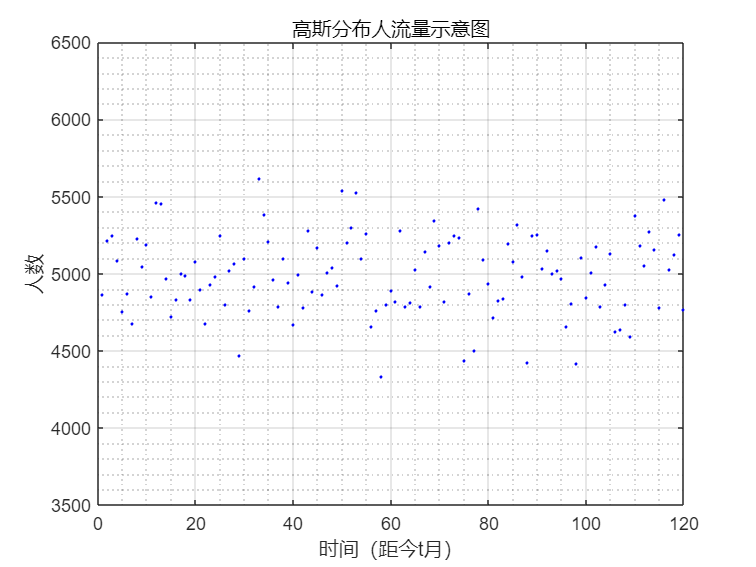

% 随机生成Q
[Q,Q1,Q2]=Q_Gaussian(Q_avg(simu_index)*9/10,Q_avg(simu_index)*11/10,1.2,T_original);
% Q,Q1,Q2均为矩阵
figure();
% 绘制点
plot(1:T_original, Q, 'b.', 'MarkerSize', 5, 'LineWidth', 2); % 蓝色圆点
% 配置图形
xlabel('时间（距今t月）');
ylabel('人数');
ylim([Q_avg(simu_index)*7/10,Q_avg(simu_index)*13/10]);
title('高斯分布人流量示意图');
grid on;grid minor;

- 对比未维修和维修的台阶磨损情况——这里只是一个引入和实验，对于接下来的分析没有用处

- （因为我们并不知道实际的d_original分布情况，我们所知道的只有d_repair）

% 原始未维修的情况
[d_original]=get_d_original(m,n,delta_S,Q1,Q2);
% 维修后的情况，也是我们实际能知道的情况
zone_0=zeros(n,m);
zone_0(33-20:33-4,50:70)=ones;
[d_repair]=get_dd_repair(0,zone_0,T_original-T_repair,a_factor,m,n,delta_S,Q1,Q2);

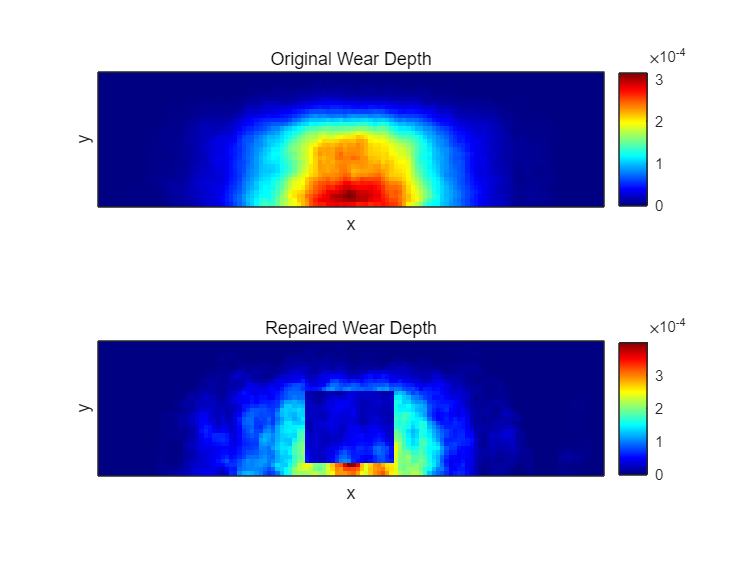

figure();
subplot(2,1,1);
imagesc(d_original);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel('x'); ylabel('y');            % 清空轴标签
title('Original Wear Depth');
% annotation('textbox', ...
%     [0.23 0.23 0.25 0.10], ...   % [x, y, width, height] in normalized figure coordinates
%     'String', sprintf('with average monthly flow of people Q=%d',Q_avg), ...
%     'FitBoxToText', 'on', ...
%     'BackgroundColor', [1 1 1], ...
%     'FontSize', 10);
subplot(2,1,2);
imagesc(d_repair);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel('x'); ylabel('y');            % 清空轴标签
title('Repaired Wear Depth');

% annotation('textbox', ...
%     [0.23 0.23 0.25 0.10], ...   % [x, y, width, height] in normalized figure coordinates
%     'String', sprintf('with average monthly flow of people Q=%d',Q_avg), ...
%     'FitBoxToText', 'on', ...
%     'BackgroundColor', [1 1 1], ...
%     'FontSize', 10);

- **梯度法检测边界**

原理是新旧材料交界处的梯度会比较大，可以用来描述边界

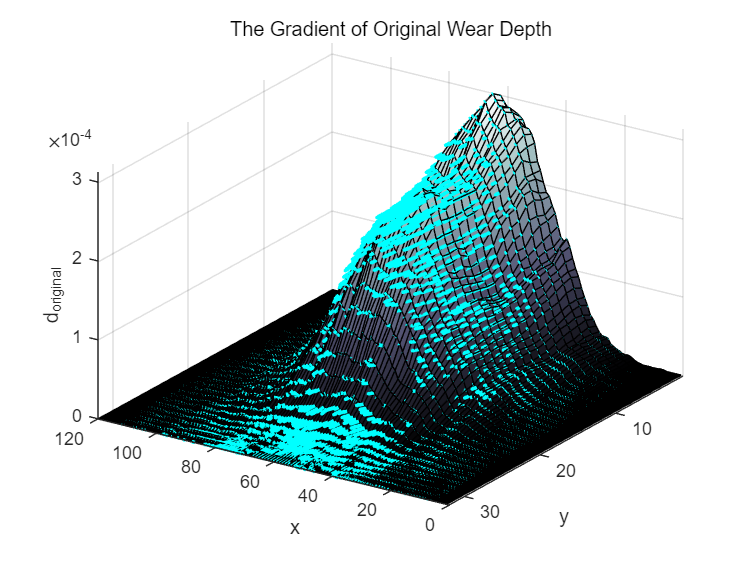

[X, Y] = meshgrid(1:1:m,1:1:n);
D_original=zeros(n,m);
D_repair=zeros(n,m);

for i=1:n
    D_original(i,:)=d_original(33-i,:);
    D_repair(i,:)=d_repair(33-i,:);
end

[FX_original, FY_original] = gradient(d_original);
[FX_repair, FY_repair] = gradient(d_repair);

g_original = FX_original.^2 + FY_original.^2 ;
g_repair = FX_repair.^2 + FY_repair.^2 ;

% 绘制原始曲面图
figure();
surf(X, Y, D_original);
colormap('bone');      % 柔和灰白
hold on;
% 在曲面上叠加梯度箭头图
quiver3(X, Y, D_original, FX_original, FY_original, zeros(size(FX_original)), ...
    'c', 'AutoScale', 'on','AutoScaleFactor', 2, 'LineWidth', 2);
title('The Gradient of Original Wear Depth');
ylim([1,32])
xlabel('x'); ylabel('y'); zlabel('d_{original}');
hold off;
% grid on;grid minor;
view([-146.2999969 32.0895015]);

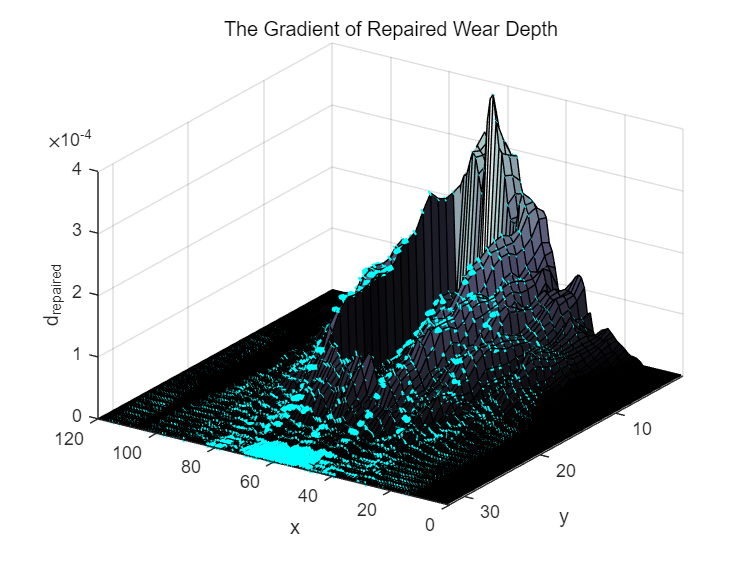

figure();
surf(X, Y, D_repair);
colormap('bone');      % 柔和灰白
hold on;
% 在曲面上叠加梯度箭头图
quiver3(X, Y, D_repair, FX_repair, FY_repair, zeros(size(FX_repair)), ...
    'c', 'AutoScale', 'on','AutoScaleFactor',3, 'LineWidth', 3);
title('The Gradient of Repaired Wear Depth');
ylim([1,32])
xlabel('x'); ylabel('y'); zlabel('d_{repaired}');
% grid on;grid minor;
hold off;
view([-146.2999969 32.0895015]);

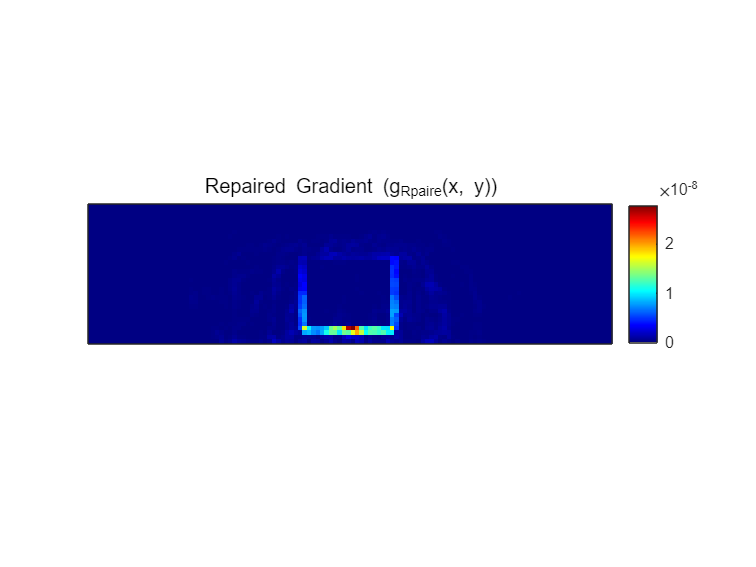

figure();
imagesc(g_repair);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
title('Repaired Gradient (g_{Rpaire}(x, y))');

max(g_repair(:))

ans = 2.7727e-08

fac_g=60

fac_g = 60

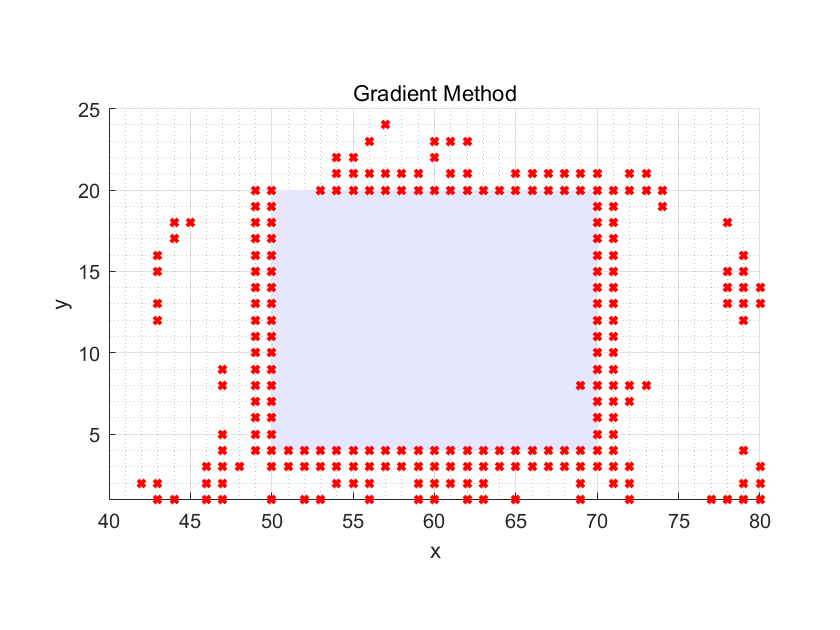

g_threshold=fac_g*1e-11;

boundary=zeros(n*m,2);
k=1;
for i=1:n % 纵坐标
    for j=1:m % 横坐标
        if g_repair(i,j)> g_threshold  % 超过阈值
            boundary(k,1)=j;
            boundary(k,2)=33-i;
            k=k+1;
        end
    end
end

figure();
% 配置图形
rectangle('Position', [50, 4, 20, 16], 'FaceColor', [0.9, 0.9, 1], 'EdgeColor', 'none');
hold on;
% 绘制点
plot(boundary(:,1), boundary(:,2), 'rx', 'MarkerSize', 5, 'LineWidth', 2); % 蓝色圆点
xlabel('x');
ylabel('y');
title('Gradient Method');
grid on;grid minor;
axis equal;
ylim([1,25]);
xlim([40,80]);

评价：梯度法的好处是比较简单方便，不需要借助模型计算，但缺点是预测不够准确，尤其是a_factor较大或者t_repaired较大时，预测将很不准确，同时对于原本磨损深度就较小的地方精度也较低

- **区域法检测是否翻新**

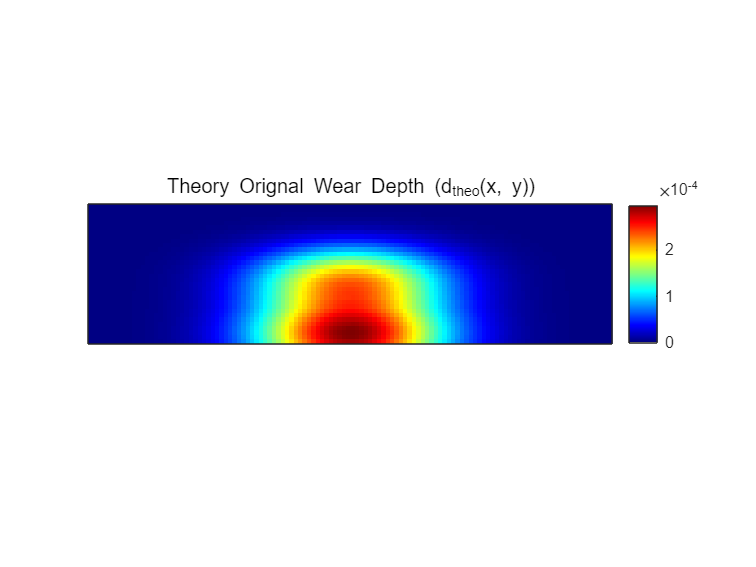

% [d_theo_org]=d_get_d_theo_org(m,n,T_original,delta_S,Q1,Q2);
load d_theo_org.mat

figure
imagesc(d_theo_org);                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
title('Theory Orignal Wear Depth (d_{theo}(x, y))');

e=zeros(n,m);
zone_estimated=zeros(n,m);
threshold=0.6

threshold = 0.6000

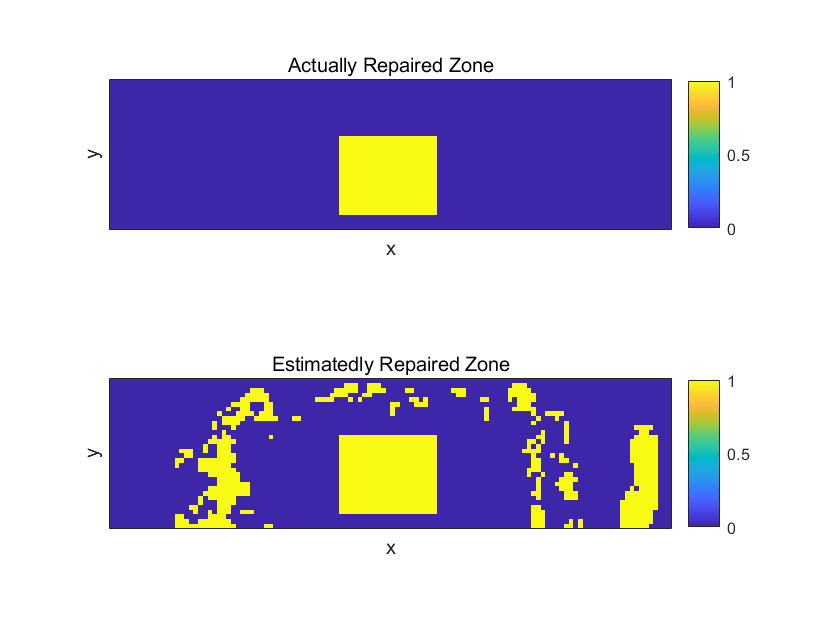

for i=1:n
    for j=1:m
        if d_theo_org(i,j)>0 &&  d_repair(i,j)>0
            e(i,j)=abs(d_repair(i,j)-d_theo_org(i,j))/d_theo_org(i,j);
        end
        if  e(i,j)>threshold
            zone_estimated(i,j)=1;
        end
    end
end

figure();
subplot(2,1,1);
imagesc(zone_0);                    % 用 imagesc 显示矩阵
colormap(parula);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel('x'); ylabel('y');            % 清空轴标签
title('Actually Repaired Zone');
subplot(2,1,2);
imagesc(zone_estimated);                    % 用 imagesc 显示矩阵
colormap(parula);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel('x'); ylabel('y');            % 清空轴标签
title('Estimatedly Repaired Zone');

评价：区域法的优点是对区域的预测精度较高，不容易混淆边界，同时对于翻新时间较久或者材料特性差异较大的情况也表现出色。但需要额外的信息（如上下行的概率，踩踏中心的概率分布），如果信息不准确反而会影响预测。

- **估测翻新时间节点**

这个问题和第五问差不多，同样可以用优化模型解决.

% 求d_theo_rep
% [d_theo_rep]=get_d_theo_rep(m,n,T_original,delta_S,Q1,Q2,zone_0,a_factor,0);
load d_theo_rep.mat;

temp=d_repair;

figure();
uuu=60

uuu = 60

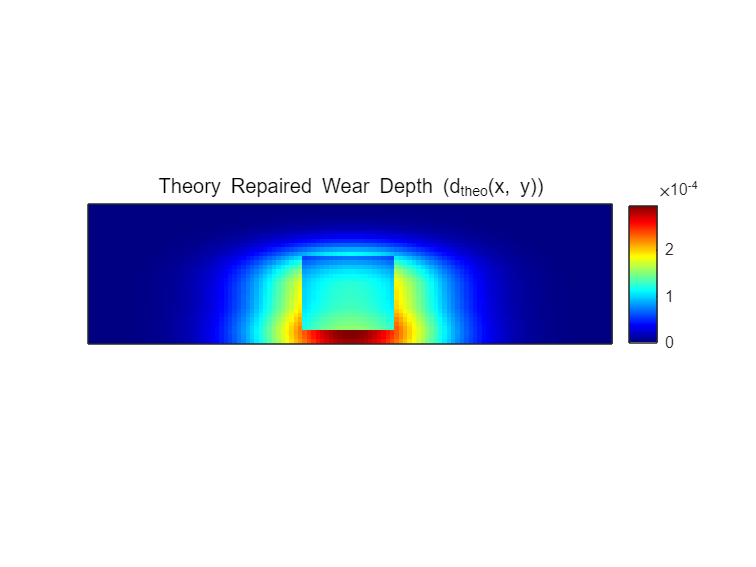

imagesc(d_theo_rep(:,:,uuu));                    % 用 imagesc 显示矩阵
colormap(jet);                 % 使用 jet 配色方案
colorbar;                      % 添加颜色条
axis equal;                    % 使网格为正方形
axis tight;                    % 去掉多余的空白
set(gca, 'XTick', [], 'YTick', []); % 移除坐标轴刻度
xlabel(''); ylabel('');            % 清空轴标签
title('Theory Repaired Wear Depth (d_{theo}(x, y))');

% 寻找最优的t_repair
E_norm=zeros(T_original,1);
% 比较各个d_theo(:,:,i)，确定出最优解t_opt
for j=1:T_original
    e=abs(d_repair-d_theo_rep(:,:,j));
    E_norm(j)=(sum(sum(e)))/(sum(sum(d_repair)));
end

[E_opt,t_opt]=min(E_norm);
disp('最小估计误差E_{opt}为');

最小估计误差E_{opt}为


disp(E_opt);

    0.2034



disp('最佳估计翻新时间t_{opt}为');

最佳估计翻新时间t_{opt}为


disp(t_opt);

    20



disp('实际翻新时间T_{repair}为');

实际翻新时间T_{repair}为


disp(T_repair);

    20



以上工作大量重复，取不同的时间T_repair，分析可靠性如下，从结果可见，误差稳定，预测精准。

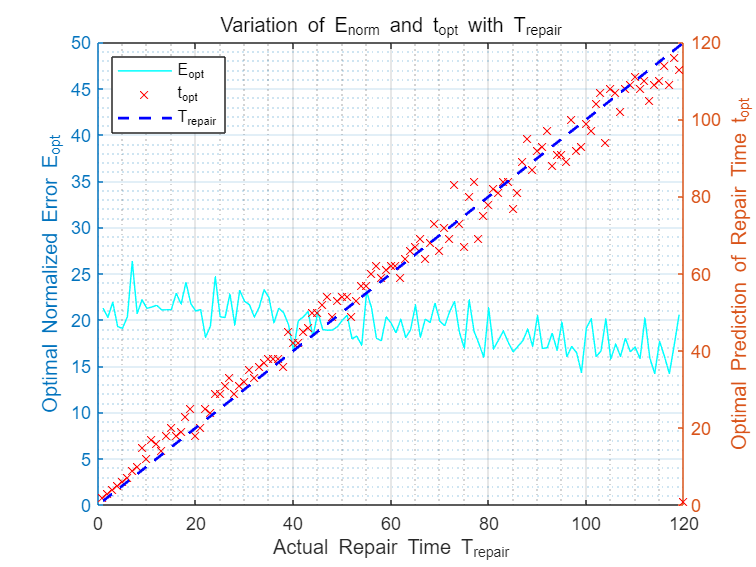

load t_opt_6.mat
load E_opt_6.mat

figure();
yyaxis left;
plot(1:120, 100*E_opt, 'c', 'LineWidth', 0.8);
hold on;
grid on; grid minor;
ylabel('Optimal Normalized Error E_{opt}');
ylim([0,50])

yyaxis right;
plot(1:120, t_opt, 'rx');
grid on; grid minor;
hold on;
plot(1:120, 1:120,'b', 'LineWidth',1.5);
grid on; grid minor;
xlabel('Actual Repair Time T_{repair}');
ylabel('Optimal Prediction of Repair Time t_{opt}');
lgd=legend("E_{opt}","t_{opt}","T_{repair}");
lgd.Location='northwest';
title('Variation of E_{norm} and t_{opt} with T_{repair}');